setenv("ROS_DOMAIN_ID","0");

setenv("ROS_DOMAIN_ID","0");
setenv("RMW_IMPLEMENTATION","rmw_fastrtps_cpp");


det = yolov8ObjectDetector('yolov8s')


%% Setup (ROS 2 + subscriber)
setenv("ROS_DOMAIN_ID","0");
setenv("RMW_IMPLEMENTATION","rmw_fastrtps_cpp");

n = ros2node("/matlab_camviewer_mlx");
det = yolov8ObjectDetector('yolov8s')
topic = "/depth_cam/rgb/image_raw/compressed";          % or /depth_cam/rgb/image_raw
msgType = "sensor_msgs/CompressedImage";                % or "sensor_msgs/Image"
reliability = "besteffort";                              % use "reliable" if topic info says Reliable

sub = ros2subscriber(n, topic, msgType, ...
    Reliability=reliability, History="keeplast", Depth=50);

%% Viewer loop (external figure; Live Editor safe)
fig = figure('Name',"ROS2 Camera: "+topic, 'NumberTitle','off', 'Visible','on');
ax  = axes('Parent',fig);
hIm = imshow(uint8(zeros(480,640,3)), 'Parent', ax);   % placeholder
title(ax, topic);

disp("📷 Streaming… close the window to stop.");
while isvalid(fig)
    [msg, ok] = receive(sub, 0.5);    % short timeout keeps UI responsive
    if ok
        img = rosReadImage(msg);
        [bboxes, scores, labels] = detect(det,img);
        annotations = string(labels) + ': ' + string(scores);
        img = insertObjectAnnotation(img, 'rectangle', bboxes, annotations);
        set(hIm, 'CData', img);
    end
    drawnow limitrate                 % process UI events
    pause(0.01)                        % Live Editor needs a tiny pause for smooth updates
end


%% Setup (ROS 2 + subscriber)
setenv("ROS_DOMAIN_ID","0");
setenv("RMW_IMPLEMENTATION","rmw_fastrtps_cpp");

n = ros2node("/matlab_camviewer_mlx");
det = yolov8ObjectDetector('yolov8s');
topic = "/depth_cam/rgb/image_raw/compressed";
msgType = "sensor_msgs/CompressedImage";
reliability = "besteffort";

sub = ros2subscriber(n, topic, msgType, ...
    Reliability=reliability, History="keeplast", Depth=50);

%% Viewer loop (external figure; Live Editor safe)
fig = figure('Name',"ROS2 Camera: "+topic, 'NumberTitle','off', 'Visible','on');
ax  = axes('Parent',fig);
hIm = imshow(uint8(zeros(480,640,3)), 'Parent', ax);   % placeholder
title(ax, topic);

disp("📷 Streaming… looking for 'person' only. Close the window to stop.");
while isvalid(fig)
    [msg, ok] = receive(sub, 0.5);    % short timeout keeps UI responsive
    if ok
        img = rosReadImage(msg);
        
        % --- MODIFICATION STEP 1 ---
        % Detect ALL objects first, without the 'Classes' parameter.
        [all_bboxes, all_scores, all_labels] = detect(det, img, 'Threshold', 0.8);
        
        % --- MODIFICATION STEP 2 ---
        % Find the indices of the results that are the "person" class.
        % We convert the categorical 'all_labels' to string for a reliable comparison.
        person_indices = (string(all_labels) == "person");
        
        % --- MODIFICATION STEP 3 ---
        % Create new variables containing only the data for the 'person' detections.
        person_bboxes = all_bboxes(person_indices, :);
        person_scores = all_scores(person_indices);
        
        % Check if any persons were found
        if ~isempty(person_bboxes)
            disp('--- Person Detected ---');
            disp('BBoxes:');
            disp(person_bboxes);
            disp('Scores:');
            disp(person_scores);
            
            % Create annotations using only the filtered person data
            annotations = "person" + ': ' + string(round(person_scores, 2));
            
            % Draw ONLY the person bounding boxes on the image
            img = insertObjectAnnotation(img, 'rectangle', person_bboxes, annotations, 'Color', 'yellow', 'LineWidth', 3);
        end
        
        % Update the image viewer with the annotated image
        set(hIm, 'CData', img);
    end
    drawnow limitrate                 % process UI events
    pause(0.01)                       % Live Editor needs a tiny pause for smooth updates
end


%% --- ROS2 Camera Stream Viewer (Compressed) ---
setenv("ROS_DOMAIN_ID","0");
setenv("RMW_IMPLEMENTATION","rmw_fastrtps_cpp");

% 1) Create node
n = ros2node("/matlab_camviewer");

% 2) Subscribe to your camera topic
topic = "/depth_cam/rgb/image_raw/compressed";
sub = ros2subscriber(n, topic, "sensor_msgs/CompressedImage", ...
    Reliability="besteffort", History="keeplast", Depth=30);

% 3) Setup display window
fig = figure('Name',"ROS2 Camera: "+topic,'NumberTitle','off');
ax  = axes('Parent',fig);
h   = imshow(uint8(zeros(480,640,3)), 'Parent', ax);  % <-- only one output!
title(ax, topic);

% 4) Loop
r = ros2rate(n,15);  % target refresh rate (Hz)
reset(r)
disp("📷 Streaming... close window to stop.");
while ishandle(fig)
    [msg, ok] = receive(sub, 0.2);
    if ok
        img = rosReadImage(msg);
        set(h, 'CData', img);
        drawnow limitrate nocallbacks
    end
    waitfor(r);
end
disp("Camera stream ended.");


setenv("ROS_DOMAIN_ID", "0");
setenv("RMW_IMPLEMENTATION", "rmw_fastrtps_cpp");

% 点云查看器 (已修正坐标系)
% 这个脚本旋转了点云数据，使其符合标准的“Z轴向上”坐标系。

clear; clc;
setenv("ROS_DOMAIN_ID","0");
setenv("RMW_IMPLEMENTATION","rmw_fastrtps_cpp");

% --- ROS 节点和订阅器 (话题正确) ---
n = ros2node("/matlab_pointcloud_viewer");
pcTopic = "/depth_cam/depth/points";
pcMsgType = "sensor_msgs/PointCloud2";
subPoints = ros2subscriber(n, pcTopic, pcMsgType, ...
    Reliability="besteffort", History="keeplast", Depth=5);

disp("正在订阅: " + pcTopic);

正在订阅: /depth_cam/depth/points



%% 高性能查看器 (已根据新坐标系调整范围)
% 现在 X 是前方, Y 是侧方, Z 是上下
% 所以我们可以设置一个更合理的范围
x_lim = [0 5];   % 查看前方 0 到 5 米
y_lim = [-1 1];  % 查看左/右 2 米
z_lim = [-1 1];  % 查看下方 1 米到上方 2 米
player = pcplayer(x_lim, y_lim, z_lim);

ax = player.Axes;
ax.Title.String = "实时点云流 (已修正坐标系)";
xlabel(ax, 'X (前方)'); ylabel(ax, 'Y (左方)'); zlabel(ax, 'Z (上方)');
% ax.View = [30, 45]; % 可以取消注释以获得倾斜视角, 或让它自动调整

disp("查看器已打开。正在等待数据...");

查看器已打开。正在等待数据...



%% 最小处理循环
while ishandle(player.Axes.Parent)
    
    [pcMsg, ok] = receive(subPoints, 2);
    
    if ok
        % 使用 rosReadXYZ 读取原始 N x 3 坐标矩阵
        locations_raw = rosReadXYZ(pcMsg);
        
        % --- 这是关键的坐标系转换 ---
        %   New X = Old Z  (前方)
        %   New Y = -Old X (左方)
        %   New Z = -Old Y (上方)
        locations_transformed = [locations_raw(:,3), -locations_raw(:,1), -locations_raw(:,2)];
        
        % 使用转换后的坐标进行显示
        view(player, locations_transformed);
    else
        disp("正在等待消息...");
    end
    
    drawnow limitrate;
end


## YOLO + Point Clould



% Combined Point Cloud Viewer and YOLOv8 Image Detector (Optimized for Low Latency)
% This script subscribes to a PointCloud2 topic and a CompressedImage topic.
% It displays the point cloud in a 3D player with a corrected coordinate system
% and displays the RGB image in a separate figure with YOLOv8 object detections.

clear; clc;

%% --- Configuration & Setup ---
% Use a faster model if 'yolov8s' is too slow. 'yolov8n' (nano) is the fastest.
yoloModel = 'yolov8s'; 

% Run YOLO detection only on every N-th frame to reduce computational load.
% A value of 4 means 1 detection for every 4 frames received.
frameSkipRate = 4;

%% --- ROS 2 Setup (Single Node for both Subscribers) ---
setenv("ROS_DOMAIN_ID", "0");
setenv("RMW_IMPLEMENTATION", "rmw_fastrtps_cpp");

% Create a single ROS 2 node for the application
n = ros2node("/matlab_vision_viewer");

% Load the YOLOv8 detector once at the beginning
disp("Loading YOLOv8 detector (" + yoloModel + ")...");

Loading YOLOv8 detector (yolov8s)...


detector = yolov8ObjectDetector(yoloModel);

Pretrained yolov8s network already exists.



disp("Detector loaded.");

Detector loaded.



%% --- Subscribers (for Point Cloud and Image) ---
% 1. Point Cloud Subscriber
pcTopic = "/depth_cam/depth/points";
pcMsgType = "sensor_msgs/PointCloud2";
subPoints = ros2subscriber(n, pcTopic, pcMsgType, ...
    Reliability="besteffort", History="keeplast", Depth=5);

% 2. Compressed Image Subscriber with low Depth to prevent lag
imgTopic = "/depth_cam/rgb/image_raw/compressed";
imgMsgType = "sensor_msgs/CompressedImage";
subImage = ros2subscriber(n, imgTopic, imgMsgType, ...
    Reliability="besteffort", History="keeplast", Depth=1);

disp("Subscribing to:");

Subscribing to:


disp("  - PointCloud: " + pcTopic);

  - PointCloud: /depth_cam/depth/points


disp("  - Image: " + imgTopic);

  - Image: /depth_cam/rgb/image_raw/compressed



%% --- Visualization Setup (Two separate windows) ---
% 1. Point Cloud Player Setup
x_lim = [0 5];   y_lim = [-2 2];  z_lim = [-1 2];
player = pcplayer(x_lim, y_lim, z_lim);
ax_pc = player.Axes;
ax_pc.Title.String = "Real-time Point Cloud (Z-up)";
xlabel(ax_pc, 'X (Forward)'); ylabel(ax_pc, 'Y (Left)'); zlabel(ax_pc, 'Z (Up)');

% 2. Image Figure Setup
fig_img = figure('Name', "YOLOv8 Detections: " + imgTopic, 'NumberTitle', 'off', 'Visible', 'on');
ax_img = axes('Parent', fig_img);
hIm = imshow(uint8(zeros(480, 640, 3)), 'Parent', ax_img);
title(ax_img, imgTopic);

%% --- Main Processing Loop ---
disp("Viewers are open. Streaming data... Close either window to stop.");

Viewers are open. Streaming data... Close either window to stop.



% %% --- FIX ---
% Initialize variables for annotations *before* the loop starts.
% This replaces the incorrect use of the 'persistent' keyword.
lastBboxes = [];
lastScores = [];
lastLabels = [];
frameCount = 0;

while ishandle(player.Axes.Parent) && isvalid(fig_img)

    % --- Process Point Cloud Data ---
    [pcMsg, pc_ok] = receive(subPoints, 0.01); 
    if pc_ok
        locations_raw = rosReadXYZ(pcMsg);
        locations_transformed = [locations_raw(:,3), -locations_raw(:,1), -locations_raw(:,2)];
        view(player, locations_transformed);
    end

    % --- Process Image Data ---
    [imgMsg, img_ok] = receive(subImage, 0.01); 

    if img_ok
        frameCount = frameCount + 1;
        img = rosReadImage(imgMsg);
        
        % Only run the heavy 'detect' function periodically
        if mod(frameCount, frameSkipRate) == 0
            [bboxes, scores, labels] = detect(detector, img);
            % Store the results for the next frames
            lastBboxes = bboxes;
            lastScores = scores;
            lastLabels = labels;
        end
        
        % Always draw annotations on every frame using the last known results.
        if ~isempty(lastLabels)
            annotations = string(lastLabels) + ': ' + string(round(lastScores, 2)); % round scores for cleaner look
            img = insertObjectAnnotation(img, 'rectangle', lastBboxes, annotations, 'LineWidth', 2, 'FontSize', 12, 'Color', 'yellow');
        end
        
        % Update the image display on every frame.
        set(hIm, 'CData', img);
    end
    
    drawnow('limitrate');
end


## YOLO Bounding Box test

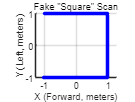


% Sanity Check Script for LiDAR Plotting
% This script creates a fake 'LaserScan' message representing a square
% and plots it. It does not use any ROS subscribers.
% If this shows a square, the plotting logic is correct.

clear; clc;

% --- 1. Create a Fake Scan Message Structure ---
fakeScan = struct();
fakeScan.angle_min = -pi;       % -180 degrees
fakeScan.angle_max = pi;        % +180 degrees
fakeScan.angle_increment = deg2rad(1); % 1 degree steps
fakeScan.ranges = ones(1, 360) * inf; % Start with all ranges as infinity

% --- 2. Define the 'Square' in the Data ---
% The logic here is to set the range to 1.0m for the four sides of a square.
angles_deg = -179:180; % Full range of angles

for i = 1:numel(angles_deg)
    angle = angles_deg(i);
    
    % Front side (from -45 to 45 deg)
    if abs(angle) <= 45
        fakeScan.ranges(i) = 1.0 / cosd(angle); % distance is 1.0m / cos(theta)
    end
    
    % Right side (from 45 to 135 deg)
    if angle > 45 && angle <= 135
        fakeScan.ranges(i) = 1.0 / cosd(angle - 90);
    end
    
    % Left side (from -135 to -45 deg)
    if angle < -45 && angle >= -135
        fakeScan.ranges(i) = 1.0 / cosd(angle + 90);
    end
end


% --- 3. Plot the Fake Data (using the exact same logic as our main script) ---
fig_lidar = figure('Name', 'LiDAR Sanity Check', 'NumberTitle', 'off');
ax_lidar = axes('Parent', fig_lidar);
hold(ax_lidar, 'on'); grid(ax_lidar, 'on'); axis(ax_lidar, 'equal');
title(ax_lidar, 'Fake "Square" Scan');
xlabel(ax_lidar, 'X (Forward, meters)'); ylabel(ax_lidar, 'Y (Left, meters)');

ranges = fakeScan.ranges;
angles = linspace(fakeScan.angle_min, fakeScan.angle_max, numel(ranges));
x = ranges .* cos(angles);
y = ranges .* sin(angles);
valid_indices = isfinite(ranges);
scatter(ax_lidar, x(valid_indices), y(valid_indices), 10, 'b', 'filled');


disp('Plotting complete. Check the figure window for a square shape.');

Plotting complete. Check the figure window for a square shape.
